load("C:\Users\Asus\Documents\MATLAB\ab_diff_zestaw.mat")

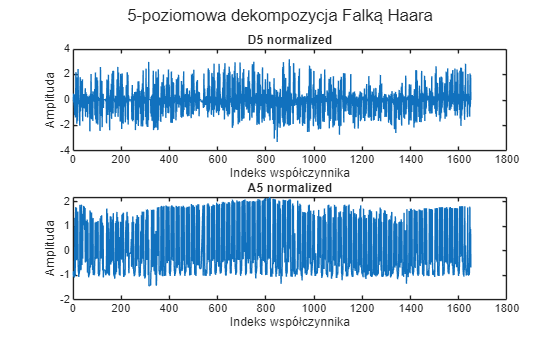

function results_py = model_hybrid(y_train, y_test, step_length,  ma_window, season_period)
    py_model = py.importlib.import_module('./python/model_hybrid');
    results_py = py_model.model_hybrid(...
        y_train, ... 
        y_test, ...
        step_length, ...
        pyargs('ma_window', ma_window, 'season_period', season_period, 'verbose', true) ...
    ).double;
end

function SARIMA_A514 = model_A5(A5)
    A51 = A5(:,1);
    SARIMA_A514 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',[1,2],'SARLags',[21,42],'Seasonality',21,'SMALags',[21,42],'Distribution','Gaussian');
    %SARIMA_A514 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',1:2,'SARLags',[147,294],'Seasonality',147,'SMALags',[147,294],'Distribution','Gaussian');
    SARIMA_A514 = estimate(SARIMA_A514,A51,'Display','off');
end


% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);


% ZBIÓR TRENINGOWY
[c, l] = wavedec(ab_diff_train_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji A i szczegółów D
A1 = appcoef(c, l, 'haar', 1);
A5 = appcoef(c, l, 'haar', 5);

D5 = detcoef(c, l, 5);
D4 = detcoef(c, l, 4);
D3 = detcoef(c, l, 3);
D2 = detcoef(c, l, 2);
D1 = detcoef(c, l, 1);

% normalizacja współczynników
[D5_norm, center_D5, scale_D5] = normalize(D5);
[A5_norm, center_A5, scale_A5] = normalize(A5);

% 2. RYSOWANIE WYKRESÓW
figure;

subplot(2, 1, 1);
plot(D5_norm);
title('D5 normalized');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

subplot(2, 1, 2);
plot(A5_norm);
title('A5 normalized');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

sgtitle('5-poziomowa dekompozycja Falką Haara');


% TEST
[c_test, l_test] = wavedec(ab_diff_test_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (Trend) z poziomu 5
A1_test = appcoef(c_test, l_test, 'haar', 1);
A5_test = appcoef(c_test, l_test, 'haar', 5);

D5_test = detcoef(c_test, l_test, 5);
D4_test = detcoef(c_test, l_test, 4);
D3_test = detcoef(c_test, l_test, 3);
D2_test = detcoef(c_test, l_test, 2);
D1_test = detcoef(c_test, l_test, 1);

% Normalizacja współczynników testowych
D5_test_norm = (D5_test - center_D5) ./ scale_D5;
A5_test_norm = (A5_test - center_A5) ./ scale_A5;

forecast_horizont = 32 * 542;

% Przewidywania A1 - model hybrydowy
D5_pred_norm = model_hybrid(D5_norm, D5_test(1:200), 96, 32, 96*7);

Error using <a href="matlab:matlab.lang.internal.introspective.errorDocCallback('<frozen importlib>_find_and_load_unlocked', '<frozen importlib._bootstrap>', 1335)" style="font-weight:bold"><frozen importlib>_find_and_load_unlocked</a> (<a href="matlab: opentoline('<frozen importlib._bootstrap>',1335,0)">line 1335</a>)
Python Error: ModuleNotFoundError: No module named 'model_hybrid'

Error in <a href="matlab:matlab.lang.internal.introspective.errorDocCallback('<frozen importlib>_find_and_load', '<frozen importlib._bootstrap>', 1371)" style="font-weight:bold"><frozen importlib>_find_and_load</a> (<a href="matlab: opentoline('<frozen importlib._bootstrap>',1371,0)">line 1371</a>)

Error in <a href="matlab:matlab.lang.internal.introspective.errorDocCallback('<frozen importlib>_gcd_import', '<frozen importlib._bootstrap>', 1398)" style="font-weight:bold"><frozen importlib>_gcd_import</a> (<a href="matlab: opentoline('<frozen importlib._bootstrap>',1398,0)">line 1398</a>)

Error in <a href

% Narysuj wykres
%D1_pred_norm = D1_pred.double;
figure;
hold on;
plot(ab_diff_test.Time(1:length(D5_test_norm)), D5_test_norm, 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:length(D5_pred_norm)), D5_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred D5 normalized');
legend;

% Przewidywania A5 - model SARIMA
Mdl_A5 = model_A5(A5_norm);
A5_pred_norm = forecast(Mdl_A5, forecast_horizont/32, 'Y0', A5_norm);

% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:length(A5_test_norm)), A5_test_norm, 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:length(A5_pred_norm)), A5_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred A5 normalized');
legend;

% DENORMALIZACJA
% Odwracamy proces: x = y * scale + center
A5_pred = (A5_pred_norm .* scale_A5) + center_A5;
D5_pred = (D5_pred_norm .* scale_D5) + center_D5;

% Obliczamy długości wektorów dla brakujących poziomów (dla zadanego horyzontu)
len_A5 = length(A5_pred);
len_D5 = len_A5;      % Z własności Haara
len_D4 = len_A5 * 2;
len_D3 = len_A5 * 4;
len_D2 = len_A5 * 8;
len_D1 = length(D1_pred);

% Budowa wektora c_pred
c_pred = [
    A5_pred;              % Predykcja SARIMA
    zeros(len_D5, 1);     % D5 - zerujemy
    zeros(len_D4, 1);     % D4 - zerujemy
    zeros(len_D3, 1);     % D3 - zerujemy
    zeros(len_D2, 1);     % D2 - zerujemy
    D1_pred               % Predykcja Hybrid
];

total_len = length(c_pred); % To uproszczenie, waverec policzy
l_pred = [
    length(A5_pred);
    length(A5_pred);      % D5
    length(A5_pred)*2;    % D4
    length(A5_pred)*4;    % D3
    length(A5_pred)*8;    % D2
    length(D1_pred);      % D1
    length(D1_pred)*2     % Całkowita długość sygnału
];

final_prediction = waverec(c_pred, l_pred, 'haar');      % podejście: A5 SARIMA i D1 HYBRYDA

y_test = ab_diff_test_norm(1:length(final_prediction))';

mae_score = mae(y_test, final_prediction')
mape_score = mape(y_test, final_prediction')
rmse_score = rmse(y_test, final_prediction')
r2_classic = R2_classic(y_test, final_prediction')
r2_alt = R2_alt(y_test, final_prediction')


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(final_prediction)), ab_diff_test_norm(1:length(final_prediction)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(final_prediction)), final_prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja Holt Winters: D5 i A5")
legend;

% Wywołaj funkcję zapisu
%zapiszWynikiPrognozy(data_names, original_data_cell, prediction_data_cell, metrics_cell);
